# Import Required Data

burnsideDir = ['/Users/lukemartin/Library/CloudStorage/OneDrive-McGillUniversity/' ...
    'Undergrad/Lab Work/2026 Summer Research/Data/8 Minute CSVs/Cloud Classified Data/Sky Classified Burnside.csv'];
gaultBaseDir = ['/Users/lukemartin/Library/CloudStorage/OneDrive-McGillUniversity/' ...
    'Undergrad/Lab Work/2026 Summer Research/Data/8 Minute CSVs/Cloud Classified Data/Sky Classified Gault.csv'];

burnsideDataUntitled = readtimetable(burnsideDir);
gaultDataUntitled = readtimetable(gaultBaseDir);

# Recompile Once Again

% Do the agonizing recompiling
allVariables = 1:width(burnsideDataUntitled);

% Fix the column titles & extract wavenumber
wavenumbers = round(table2array(burnsideDataUntitled(1, 1:end-1)), 3);

wavenumberTitles = arrayfun(@(x) num2str(x), wavenumbers, 'UniformOutput', false);


newTitle = string([wavenumberTitles, {"Clouds"}]);
burnsideDataUntitled(1, :) = [];
gaultDataUntitled(1, :) = [];

% Annoying that I have to do this, but whatever

burnsideData = table2array(renamevars(burnsideDataUntitled, allVariables, newTitle));
gaultData = table2array(renamevars(gaultDataUntitled, allVariables, newTitle));

# Divide into cloudy and clear

% Divide into cloudy and clear

clearBurnsideData = burnsideData((find(burnsideData(:, end) == 0)), :);
clearBurnsideData(:, end) = [];

cloudyBurnsideData = burnsideData((find(burnsideData(:, end) == 1)), :);
cloudyBurnsideData(:, end) = [];


% Take averages of each wavenumber

averageClear = mean(clearBurnsideData, "omitmissing");
averageCloudy = mean(cloudyBurnsideData, "omitmissing");

# Make Simple Plots of Averages

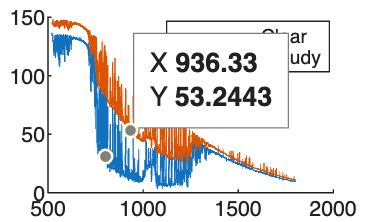

figure
hold on
plot(wavenumbers, averageClear)
plot(wavenumbers, averageCloudy)
legend("Clear", "Cloudy", Location = 'best')
hold off